clear; clc; close all;

%% ========================= USER CONTROLS ================================
rng(7);                      % reproducibility
SHOW_PLOTS           = true; % minimal plots
SAVE_RESULTS_TO_CSV  = true; % write results.csv

% Layout
cellRadius     = 500;         % meters
numTiers       = 1;           % 7 cells (center + 6)
sectorsPerCell = 3;           % 3-sector sites
usersPerSector = 12;          % try 2 to see PRB sharing in action
sectorSpanDeg  = 120;         % sector width
sectorAngles   = [30, 150, 270]; % sector boresight
Number_of_Subarray =10;

% Carrier and noise
fc      = 28e9;               % 28 GHz
NF_dB   = 7;                  % receiver noise figure (dB)
N0_dBm_perHz = -174;          % thermal noise density
scs     = 60e3;               % subcarrier spacing (Hz)
NscPRB  = 12;                 % subcarriers per PRB
Bprb    = NscPRB * scs;       % PRB bandwidth (Hz)


% Total BS power budget and user budget
PM_bs_W = 20;                 % 20 W per BS (aggregate)
pm_user_W  = 1;               % max total UE transmit power (W) across its PRBs
sub = 1;                      % initalize Subarray 1 * 1
% PRB pool (per sector)
total_PRBs_per_sector       = 132;
Total_Bandwidth = 100;
shareablePRBs    = [3,5,7,9,11,13];  % PRB indices that may be shared by 2 users
maxUsersPerPRB   = 2;                 % allow up to 2 on shared PRBs

% Traffic & modulation → min-SINR targets
Rk_Mbps_range = [7, 64];            % random throughput request in Mbps
MOk_choices   = [2,4,6];             % bits per symbol proxy (QPSK=2, 16QAM=4, 64QAM=6)
num_prbs = [5, 15];
SubarrayGains = [8,13,16,19,20, 21, 22, 23, 24,25];

% Channel & pathloss
Mr = 2; Mt = 2;                       % antennas (UE, BS)
extraLoss_dB = 6;                     % extra 6 dB loss (e.g., body/cable)



%% ===================== DERIVED / HELPER VALUES ==========================
% Build centers for a 7-cell hex layout
numSamples =12;
centers = [];
for sample = 1:numSamples 
for q = -numTiers:numTiers
    r1 = max(-numTiers, -q-numTiers);
    r2 = min(numTiers, -q+numTiers);
    for r = r1:r2
        x = cellRadius * 3/2 * q;
        y = cellRadius * sqrt(3) * (r + q/2);
        centers = [centers; x y];
    end
end
numBS = size(centers,1);

% PRB indices
allPRBs = 1:total_PRBs_per_sector;

% Thermal noise per PRB (Watts), with NF
I0_W = thermal_noise_per_prb(N0_dBm_perHz, Bprb, NF_dB);

%% ====================== PLACE UEs PER SECTOR ============================
UE = [];  % table-like array: [userID, bsID, sectorID, x, y, d2bs(m)]
userID = 0;
thetaHex = linspace(0, 360, 6+1);

for bs = 1:numBS
    cx = centers(bs,1); cy = centers(bs,2);
    % hex polygon
    x_hex = cx + cellRadius*cosd(thetaHex);
    y_hex = cy + cellRadius*sind(thetaHex);

    for s = 1:sectorsPerCell
        angCenter = sectorAngles(s);
        for u = 1:usersPerSector
            placed = false; tries = 100;
            while ~placed && tries>0
                rUE = cellRadius * sqrt(rand);
                angOffset = -sectorSpanDeg/2 + sectorSpanDeg*rand;
                UE_ang = angCenter + angOffset;
                ux = cx + rUE*cosd(UE_ang);
                uy = cy + rUE*sind(UE_ang);
                if inpolygon(ux,uy,x_hex,y_hex)
                    userID = userID + 1;
                    d = hypot(ux-cx, uy-cy);
                    UE = [UE; userID, bs, s, ux, uy, d];
                    placed = true;
                end
                tries = tries - 1;
            end
        end
    end
end

numUsers = size(UE,1);

% Pack into a struct array for convenience
Users = repmat(struct( ...
    'id', [], 'bs', [], 'sector', [], 'x', [], 'y', [], 'd_m', [], ...
    'MOk', [], 'Rk_Mbps', [], 'numPRBs', [], 'gamma', [], 'TL_lin', []), numUsers, 1);

for k = 1:numUsers
    Users(k).id       = UE(k,1);
    Users(k).bs       = UE(k,2);
    Users(k).sector   = UE(k,3);
    Users(k).x        = UE(k,4);
    Users(k).y        = UE(k,5);
    Users(k).d_m      = UE(k,6);
      n2 = round(0.5*numUsers);
    n4 = round(0.3*numUsers);
    n6 = numUsers - n2 - n4;
    rlist = [rand(n2,1)*0.5; 0.5 + rand(n4,1)*0.3; 0.8 + rand(n6,1)*0.2];
    rlist = rlist(randperm(numUsers));   % shuffle
    r = rlist(k);
     Users(k).Rk_Mbps = randi(Rk_Mbps_range);
     throughput =  Users(k).Rk_Mbps ;

    if throughput >= 7 && throughput < 21
        Users(k).MOk = MOk_choices(1);   % QPSK (2)
        M = 2;  
    elseif throughput >= 21 && throughput < 43
        Users(k).MOk = MOk_choices(2);   % 16QAM (4)
        M = 4;  
    elseif throughput >= 43 && throughput <= 64
        Users(k).MOk = MOk_choices(3);   % 64QAM (6)
        M = 6;  
    else
            error('Throughput out of expected range.');
    end
  
    Users(k).gamma    = sinr_min_from_MOk(Users(k).MOk); % linear
    % pathloss (FSPL + extra)
    PL_dB             = fspl_dB(fc, Users(k).d_m) + extraLoss_dB;
    Users(k).TL_lin   = 10.^(PL_dB/10); % total loss (linear)
end
end
[UserAssignment, Users] = assignSubarray(Users, SubarrayGains);



%% ======================== ASSIGN PRBs PER SECTOR ========================
Sectors(numBS, sectorsPerCell) = struct();
for bs = 1:numBS
    for s = 1:sectorsPerCell
        Sectors(bs,s).Available = allPRBs;
        Sectors(bs,s).PRBUsers = cell(1, total_PRBs_per_sector);
    end
end

Subarrays(Number_of_Subarray) = struct();

% Assign MT and RT values for each subarray
Subarrays(1).MT = 1;   Subarrays(1).RT = 1;
Subarrays(2).MT  = 3;  Subarrays(2).RT = 3;
Subarrays(3).MT  = 5;  Subarrays(3).RT = 5;
Subarrays(4).MT  = 6;   Subarrays(4).RT = 6;
Subarrays(5).MT  = 21;  Subarrays(5).RT = 2;
Subarrays(6).MT  = 21;  Subarrays(6).RT = 3;
Subarrays(7).MT  = 7;  Subarrays(7).RT = 9;
Subarrays(8).MT  = 21;  Subarrays(8).RT = 4;
Subarrays(9).MT  = 21;  Subarrays(9).RT = 5;
Subarrays(10).MT = 21; Subarrays(10).RT =7;





for k = 1:numUsers
    bs = Users(k).bs;
    s = Users(k).sector;

    % PRBs needed
    numPRBs_need = define_PRBs(Users(k).Rk_Mbps, Users(k).MOk, NscPRB, scs);
    Users(k).numPRBs = min(numPRBs_need, total_PRBs_per_sector);

    % compute channel gains for PRB ranking
    % Get currently available PRBs
    avail = Sectors(bs,s).Available;  
    
    % Compute channel gain only for available PRBs
    cg = zeros(1, length(avail));  
    for ii = 1:length(avail)
        prb = avail(ii); % actual PRB index from available set
        H = (randn(Subarrays(1).MT,Subarrays(1).RT) + 1j*randn(Subarrays(1).MT,Subarrays(1).RT))/sqrt(2);
        [V,D] = eig(H'*H);
        [~,ix] = max(real(diag(D)));
        t = V(:,ix); 
        t = t / norm(t);
        v = H*t; 
        r = conj(v);
        cg(ii) = abs(r'*(H*t))^2 / Users(k).TL_lin;
    end
    
    % Sort the channel gains among available PRBs
    [~, idx] = sort(cg, 'descend');
    
    % Pick the top PRBs for this user (limited by need and availability)
    num_needed = min(Users(k).numPRBs, length(idx));
    take_from_avail = avail(idx(1:num_needed));
    
    % Assign PRBs to the user
    prbs_assigned = take_from_avail;
    
    % Remove assigned PRBs from sector availability
    Sectors(bs,s).Available = setdiff(Sectors(bs,s).Available, take_from_avail, 'stable');

    % shareable PRBs if needed
    need = Users(k).numPRBs - numel(prbs_assigned);
    if need>0
        for prb = shareablePRBs
            if need==0, break; end
            curUsers = Sectors(bs,s).PRBUsers{prb};
            if numel(curUsers) < maxUsersPerPRB
                prbs_assigned(end+1) = prb;
                need = need - 1;
            end
        end
    end

    Users(k).PRBs = unique(prbs_assigned, 'stable');
    for prb = Users(k).PRBs
        Sectors(bs,s).PRBUsers{prb} = [Sectors(bs,s).PRBUsers{prb}, k];
    end
end



%% ===================== POWER ALLOCATION PER SECTOR/PRB ==================

function ResultsPRB = powerAllocationPerPRB(numBS, sectorsPerCell, total_PRBs_per_sector, Sectors, Users,Subarray, I0_W)
                                        
MT = Subarray.MT;
RT = Subarray.RT;
ResultsPRB = []; % temporary results, per PRB-user
row = 0;
total_PRBs_per_sector       = 132;
Total_Bandwidth = 100 * 10^6;
for bs = 1:numBS
    for s = 1:sectorsPerCell
        for prb = 1:total_PRBs_per_sector
            userIdx = Sectors(bs,s).PRBUsers{prb};
            Nu = numel(userIdx);
            if Nu==0, continue; end

            H_list  = cell(1,Nu);
            t_list  = cell(1,Nu);
            r_list  = cell(1,Nu);
            TL_list = zeros(1,Nu);
            gamma_list = zeros(1,Nu);
            rks = zeros(1, Nu);

            for u = 1:Nu
                k = userIdx(u);
                H = (randn(RT,MT)+1j*randn(RT,MT))/sqrt(2);
                t = compute_tks(H);
                r = conj(H*t);

                H_list{u}  = H;
                t_list{u}  = t;
                r_list{u}  = r;
                TL_list(u) = Users(k).TL_lin;

                gk = Users(k).gamma;
                if numel(gk) > 1, gk = gk(prb); end
                gamma_list(u) = gk;
            end

            [C, D, ~, ~] = build_C_D(H_list, t_list, r_list, TL_list, gamma_list, I0_W);
            [p, feasible] = solve_power(C, D);
            ach = achieved_sinr(H_list, t_list, r_list, TL_list, p, I0_W);
            rks = compute_rks(ach , Total_Bandwidth, total_PRBs_per_sector );


            for u = 1:Nu
                row = row + 1;
                k = userIdx(u);

                ResultsPRB(row).BS       = bs;
                ResultsPRB(row).Sector   = s;
                ResultsPRB(row).UserID   = Users(k).id;
                ResultsPRB(row).Power_W  = p(u);
                ResultsPRB(row).SINR_dB  = ach(u);
                ResultsPRB(row).RK_S     = rks(u);
                ResultsPRB(row).Feasible = double(feasible);
                % disp(ach(u));
            end
        end
    end
end
end

% report

function [UserSummary, T] =reportPowerAllocation(ResultsPRB, Users, numUsers, ...
    numBS, sectorsPerCell, total_PRBs_per_sector, Sectors, I0_W, ...
    pm_user_W, PM_bs_W, Subarrays, SAVE_RESULTS_TO_CSV, SHOW_PLOTS)


% reportPowerAllocation
% Wraps your REPORTING code into a function.
% Usage:
%   [UserSummary, T] = reportPowerAllocation(ResultsPRB, Users, numUsers, numBS, ...
%       pm_user_W, PM_bs_W, SAVE_RESULTS_TO_CSV, SHOW_PLOTS);

%% ============================ REPORTING ================================
if isempty(ResultsPRB)
    warning('No PRBs were allocated. Increase usersPerSector or total_PRBs.');
    UserSummary = table();   % return empty artifacts to match behavior
    T = table();
else
    T = struct2table(ResultsPRB);
    


    % === Per-user summary ===
    % === Per-user summary ===
Results = struct();


for k = 1:numUsers
    userMask = (T.UserID == Users(k).id);
    totalP   = sum(T.Power_W(userMask));
    if totalP < 0.1
    totalP = 0.1;   % realistic per-user average (you can also try 0.1)
    end
    RK_S     = sum(T.RK_S (userMask));
    Results(k).BS             = Users(k).bs;
    Results(k).Sector         = Users(k).sector;
    Results(k).UserID         = Users(k).id;
    Results(k).AssignedPRBs   = numel(Users(k).PRBs);   % actually allocated
    %Results(k).RequestedPRBs  = Users(k).numPRBs;
    Results(k).Rk_Mbps        = Users(k).Rk_Mbps;
    Results(k).MOk            = Users(k).MOk;
    Results(k).maximum_throughput   = RK_S ;
    Results(k).TotalPower_W   = totalP;
    %Results(k).Select_Subarrays   = Users(k).AssignedSubarray ;
    
    
    
end

    

    % Compute per-BS totals
    BS_totals = accumarray(T.BS, T.Power_W, [numBS 1], @sum);

    % Add BS total and flags
    for k = 1:numUsers
        bs_id = Results(k).BS;
        Results(k).BSTotalPower_W = BS_totals(bs_id);

        % Flags
        %Results(k).UserMeetPower = double(Results(k).TotalPower_W <= pm_user_W);
        %Results(k).BSMeetPower   = double(Results(k).BSTotalPower_W <= PM_bs_W);
    end
    
        %UserSummary = struct2table(Results);
        
        %% ======================= POWER RE-ALLOCATION LOGIC ======================
        % Apply control logic similar to algorithm lines 12–23
    rf = 1;  % reallocation flag
    ru = 0;  % reallocation counter
    % sub = 1;
    % ================================================================
    % Power Validation and Reallocation Logic
    % ================================================================
    
    pm_user_W = 1;     % Power threshold per user (W)
    PM_bs_W   = 20;    % Power threshold per base station (W)

    % Step 1: Process users normally
    for k = 1:numUsers
        bs_id = Results(k).BS;
        userP = Results(k).TotalPower_W;
         if userP < 0.1
           userP = 0.1;   % realistic per-user average power
           Results(k).TotalPower_W = userP;
        end
        Results(k).Select_Subarrays   = Users(k).AssignedSubarray ;
        sub = Results(k).Select_Subarrays ;
        % Compute current total (approx)
        bsP = sum([Results([Results.BS] == bs_id).TotalPower_W]);
        
        if (userP <= pm_user_W) && (bsP <= PM_bs_W)
            %Results(k).Valid = true;
             Results(k).BSTotalPower_W = bsP;
             Results(k).SelectedSubarray = sub;
            continue;
        else
            rf = 1; sub = Users(k).AssignedSubarray;
            while (rf > 0) && (sub <= numel(Subarrays))
                selectedSub = Subarrays(sub);
                NewResultsPRB = powerAllocationPerPRB(numBS, sectorsPerCell, ...
                    total_PRBs_per_sector, Sectors, Users, selectedSub, I0_W);
                
                T_new = struct2table(NewResultsPRB);
                userMask = (T_new.UserID == Results(k).UserID);
                newUserPower = sum(T_new.Power_W(userMask));
                if newUserPower < 0.1
                   newUserPower = 0.1;  % realistic replacement
                end
                newBsPower = sum(T_new.Power_W(T_new.BS == bs_id));
                
                if (newUserPower <= pm_user_W) && (newBsPower <= PM_bs_W)
                    rf = 0;
                    Results(k).TotalPower_W = newUserPower;
                    Results(k).SelectedSubarray = sub;
                    %Results(k).Valid = true;
                else
                    rf = 1;
                    sub = sub + 1;
                    %Results(k).Valid = false;
                end
            end
        end
    end
    
    % Step 2: After finishing all users, compute BS total power accurately
    uniqueBS = unique([Results.BS]);
    for b = 1:numel(uniqueBS)
        bs_id = uniqueBS(b);
        BSTotalPower = sum([Results([Results.BS] == bs_id).TotalPower_W]);
        
        % Assign same BS total to all users in this BS
        for k = find([Results.BS] == bs_id)
            Results(k).BSTotalPower_W = BSTotalPower;
        end
    end




% ================================================================
% Optional: collect all valid users for easy access
% ================================================================
% ValidUsers = Results([Results.Valid] == true);
% fprintf('\nTotal valid users found: %d\n', numel(ValidUsers));

    UserSummary = struct2table(Results);
    
    %% Energy and Spectral Efficiency Calculation from Excel
    BW = 100e6;                             % 100 MHz
    filename = 'per_user_summary.csv';      % or .xlsx
    T = readtable(filename, 'PreserveVariableNames', true);
    
    % --- Sum across all users in the scenario ---
    Pks_total = sum(T.TotalPower_W);        % total power [W]
    Ru_total  = sum(T.maximum_throughput);  % total throughput [bps]
    
    % --- Compute EE & SE ---
    EE = Ru_total / max(Pks_total, eps);      
    SE = Ru_total / BW;                 
    
    fprintf('Scenario 1: Total Power = %.4f W\n', Pks_total);
    fprintf('Scenario 1: Total Throughput = %.4f bps\n', Ru_total);
    fprintf('Scenario 1: EE = %.6g bits/Joule\n', EE);
    fprintf('Scenario 1: SE = %.6g bits/s/Hz\n', SE);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



% -------------------------------
% Your measured/simulated data


% Results from the paper (non-ML)
EE_nonML = 5.0e6;     % bits/J (5 Mbits/J)
SE_nonML = 36.0;      % bits/s/Hz

% -------------------------------
% Group data for plotting
EE_values = [EE, EE_nonML];
SE_values = [SE, SE_nonML];
labels = {'Scenario 1 (Your Work)', 'Non-ML (Paper)'};

% -------------------------------
% Plot 1: Energy Efficiency comparison
figure;
bar(EE_values/1e6); % convert to Mbits/J
set(gca, 'XTickLabel', labels, 'FontSize', 12);
ylabel('Energy Efficiency (Mbits/J)', 'FontSize', 12);
title('Energy Efficiency Comparison', 'FontSize', 14);
grid on;
text(1:length(EE_values), (EE_values/1e6)*1.02, ...
    string(round(EE_values/1e6,3)), ...
    'HorizontalAlignment','center', 'FontSize',11);

% -------------------------------
% Plot 2: Spectral Efficiency comparison
figure;
bar(SE_values);
set(gca, 'XTickLabel', labels, 'FontSize', 12);
ylabel('Spectral Efficiency (bits/s/Hz)', 'FontSize', 12);
title('Spectral Efficiency Comparison', 'FontSize', 14);
grid on;
text(1:length(SE_values), SE_values*1.02, ...
    string(round(SE_values,2)), ...
    'HorizontalAlignment','center', 'FontSize',11);

% -------------------------------
% Calculate and print relative changes
rel_change_EE = ((EE - EE_nonML) / EE_nonML) * 100;
rel_change_SE = ((SE - SE_nonML) / SE_nonML) * 100;

fprintf('\n=== Comparison Results ===\n');
fprintf('Energy Efficiency:  Scenario1 = %.2f Mbits/J,  Non-ML = %.2f Mbits/J\n', EE/1e6, EE_nonML/1e6);
fprintf('→ Relative change = %.2f%%\n', rel_change_EE);
fprintf('Spectral Efficiency: Scenario1 = %.2f bps/Hz,   Non-ML = %.2f bps/Hz\n', SE, SE_nonML);
fprintf('→ Relative change = %.2f%%\n\n', rel_change_SE);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    % Save
    if SAVE_RESULTS_TO_CSV
        writetable(UserSummary, 'per_user_summary.csv');
        fprintf('Saved clean per-user dataset: per_user_summary.csv\n');
    end
    

    % % Basic plot
    % if SHOW_PLOTS
    %     figure; histogram(T.SINR_dB);
    %     xlabel('Achieved SINR (dB)'); ylabel('Count');
    %     title('Per-PRB Achieved SINR across all users');
    %     grid on;
    % 
    %     figure; histogram(UserSummary.TotalPower_W);
    %     xlabel('Total Power per User (W)'); ylabel('Count');
    %     title('User Total Powers');
    %     grid on;
    % end
end

end

Scenario 1: Total Power = 737.9765 W
Scenario 1: Total Throughput = 5784835570.0963 bps
Scenario 1: EE = 7.83878e+06 bits/Joule
Scenario 1: SE = 57.8484 bits/s/Hz


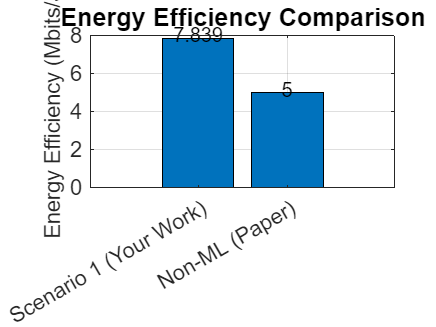

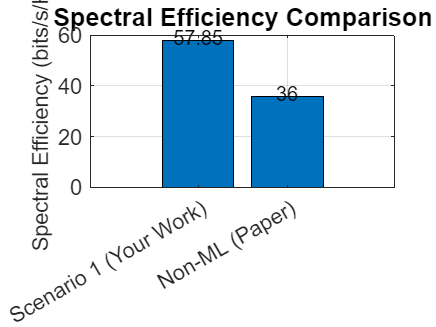


=== Comparison Results ===
Energy Efficiency:  Scenario1 = 7.84 Mbits/J,  Non-ML = 5.00 Mbits/J
→ Relative change = 56.78%
Spectral Efficiency: Scenario1 = 57.85 bps/Hz,   Non-ML = 36.00 bps/Hz
→ Relative change = 60.69%

Saved clean per-user dataset: per_user_summary.csv


ResultsPRB = powerAllocationPerPRB(numBS, sectorsPerCell, total_PRBs_per_sector, ...
                                   Sectors, Users, Subarrays(sub), I0_W);

[UserSummary, T] = reportPowerAllocation(ResultsPRB, Users, numUsers, ...
    numBS, sectorsPerCell, total_PRBs_per_sector, Sectors, I0_W, ...
    pm_user_W, PM_bs_W, Subarrays, SAVE_RESULTS_TO_CSV, SHOW_PLOTS);


%% ============================= FUNCTIONS ================================
function numPRBs = define_PRBs(Rk_Mbps, MOk, NscPRB, scs)
R_bps = Rk_Mbps*1e6;
perPRB_bps = NscPRB * scs * MOk;
numPRBs = max(1, ceil(R_bps / perPRB_bps));
end


function gamma = sinr_min_from_MOk(MOk)
switch MOk
    case 2, sinr_dB = 0;   % QPSK
    case 4, sinr_dB = 10;  % 16QAM
    case 6, sinr_dB = 17;  % 64QAM
    otherwise, sinr_dB = 0;
end
gamma = 10^(sinr_dB/10);
end


function t = compute_tks(H)
[V,D] = eig(H' * H);
[~,ix] = max(real(diag(D)));
t = V(:,ix);
if norm(t)>0, t = t / norm(t); end
end


function [C, D, g, r2] = build_C_D(H_list, t_list, r_list, TL_list, gamma_list, I0)
Ns = numel(H_list);
C = zeros(Ns, Ns);
D = zeros(Ns, 1);
g = zeros(Ns, Ns);
r2 = zeros(Ns,1);
for k = 1:Ns
    rk = r_list{k};
    r2(k) = real(rk' * rk);
    for kp = 1:Ns
        num = abs(rk' * (H_list{kp} * t_list{kp}))^2;
        g(k,kp) = num / TL_list(kp);
    end
end
for k = 1:Ns
    C(k,k) = g(k,k);
    for kp = 1:Ns
        if kp~=k
            C(k,kp) = -5 * g(k,kp);
        end
    end
    D(k) = 5 * r2(k) * I0;
end
end



function [p, feasible] = solve_power(C, D)
if rcond(C) < 1e-12
    C = C + 1e-12*eye(size(C));
end
p = C \ D;
feasible = all(isfinite(p)) && all(p >= -1e-12);
p = max(p, 0);
end


function ach = achieved_sinr(H_list, t_list, r_list, TL_list, p, I0)
Ns = numel(H_list);
ach = zeros(Ns,1);
for k = 1:Ns
    rk = r_list{k};
    desired = p(k) * (abs(rk' * (H_list{k} * t_list{k}))^2) / TL_list(k);
    interf = 0;
    for kp = 1:Ns
        if kp==k, continue;
        end
        interf = interf + p(kp) * (abs(rk' * (H_list{kp} * t_list{kp}))^2) / TL_list(kp);
    end
    noise = (rk' * rk) * 4.00e-13;
    ach(k) = real(desired) / (real(interf) + real(noise) + 1e-18);
end
end

function rks = compute_rks(ach, Total_Bandwidth, total_PRBs_per_sector)
% compute_rks  Compute the maximum achievable throughput per PRB
%   using the Shannon capacity formula.
%
%   rks = compute_rks(SINR_dB, W, NPRB)
%
%   Inputs:
%       RK_SRK_SRK_SRK_SRK_S
%       W       : Total system bandwidth in Hz (e.g., 20e6 for 20 MHz)
%       NPRB    : Total number of PRBs in the system
%
%   Output:
%       rks     : Achievable rate(s) per PRB in bits per second (bps)

   

    % Shannon capacity formula per PRB
    rks = (Total_Bandwidth / total_PRBs_per_sector) * log2(1 + ach );
    

end




function PL_dB = fspl_dB(fc_Hz, d_m)
d_km = max(d_m, 1e-3)/1000;
fc_MHz = fc_Hz/1e6;
PL_dB = 32.4 + 20*log10(fc_MHz) + 20*log10(d_km);
end

function I0_W = thermal_noise_per_prb(N0_dBm_perHz, B_Hz, NF_dB)
N0_W_perHz = 10^((N0_dBm_perHz - 30)/10);
Noise_W = N0_W_perHz * B_Hz;
I0_W = Noise_W * 10^(NF_dB/10);
end

function [UserAssignment, Users] = assignSubarray(Users, SubarrayGains)

MinRate = 7;
MaxRate = 64;
NumUsers = numel(Users);
UserAssignment = zeros(NumUsers,1);

Gmin = min(SubarrayGains);
Gmax = max(SubarrayGains);

for k = 1:NumUsers
    reqRate = Users(k).Rk_Mbps;
    reqGain = Gmin + (reqRate - MinRate) / (MaxRate - MinRate) * (Gmax - Gmin);
    
    candidate = find(SubarrayGains >= reqGain);
    
    if isempty(candidate)
        % fallback if no sub-array satisfies the requirement
        UserAssignment(k) = find(SubarrayGains == max(SubarrayGains), 1);
    else
        [~, idx] = min(SubarrayGains(candidate));
        UserAssignment(k) = candidate(idx);
    end
    
    % store in Users structure
    Users(k).AssignedSubarray = UserAssignment(k);
end
end